# Project - Stellar Motion II

- **Load the "**starData.mat**" from the previous project.**

load('live_scripts_and_data\starData.mat')

%Calculate the speed of all the stars in the spectra
[sHa,idx] = min(spectra);
lambdaHa = lambda(idx);
z = lambdaHa/656.28 - 1;
speed = z*299792.458

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


%Plot the spectra of all seven stars using different 
%line properties for redshifted and blueshifted spectra.
for v = 1:7
    s = spectra(:, v)
    if speed(v) <= 0
        %plots 's' against 'lambda' if the condition is true
        plot(lambda, s, '--')
        hold on
    elseif speed(v) > 0
        %plots 's' against 'lambda' withbold lines if condition is true
        plot(lambda, s, "LineWidth", 3)
    end
    hold on
end

s = 1.0e-12 *

    0.3088
    0.3136
    0.3105
    0.3076
    0.3088
    0.3105
    0.3122
    0.3101
    0.3078
    0.3047


s = 1.0e-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


s = 1.0e-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249


s = 1.0e-13 *

    0.8919
    0.8981
    0.9152
    0.9311
    0.9355
    0.9321
    0.9286
    0.9247
    0.9240
    0.9177


s = 1.0e-12 *

    0.1088
    0.1084
    0.1104
    0.1124
    0.1122
    0.1136
    0.1138
    0.1130
    0.1124
    0.1108


s = 1.0e-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


s = 1.0e-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


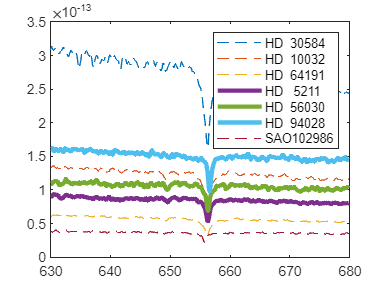

hold off

%Adds legends
legend(starnames)

%stores elements in starnames that are greater than '0' to the array "movaway".
movaway = starnames(speed > 0)

movaway = 3×1 string array
    "HD   5211"
    "HD  56030"
    "HD  94028"


`Additional`

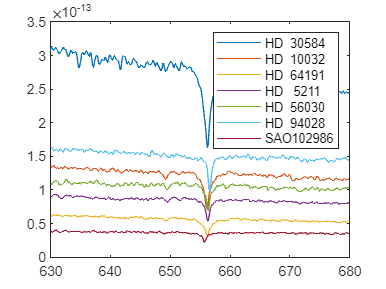

%Plot without differentiating between redshifted and blueshifted spectra.
plot(lambda, spectra)
legend(starnames)